# DAAP HW1

*Alberto Doimo 10865196*

*Paolo Ostan 10868276*

## **Talking Instrument creation **

### **Parameters initialization**

clc; close all; clear all;

instr_name = "piano.wav";
speech_name = "speech.wav";
talking_instr_res_name = "talking_instr_res.wav";

### 01) First test with verbose parameters to check functioning of the script

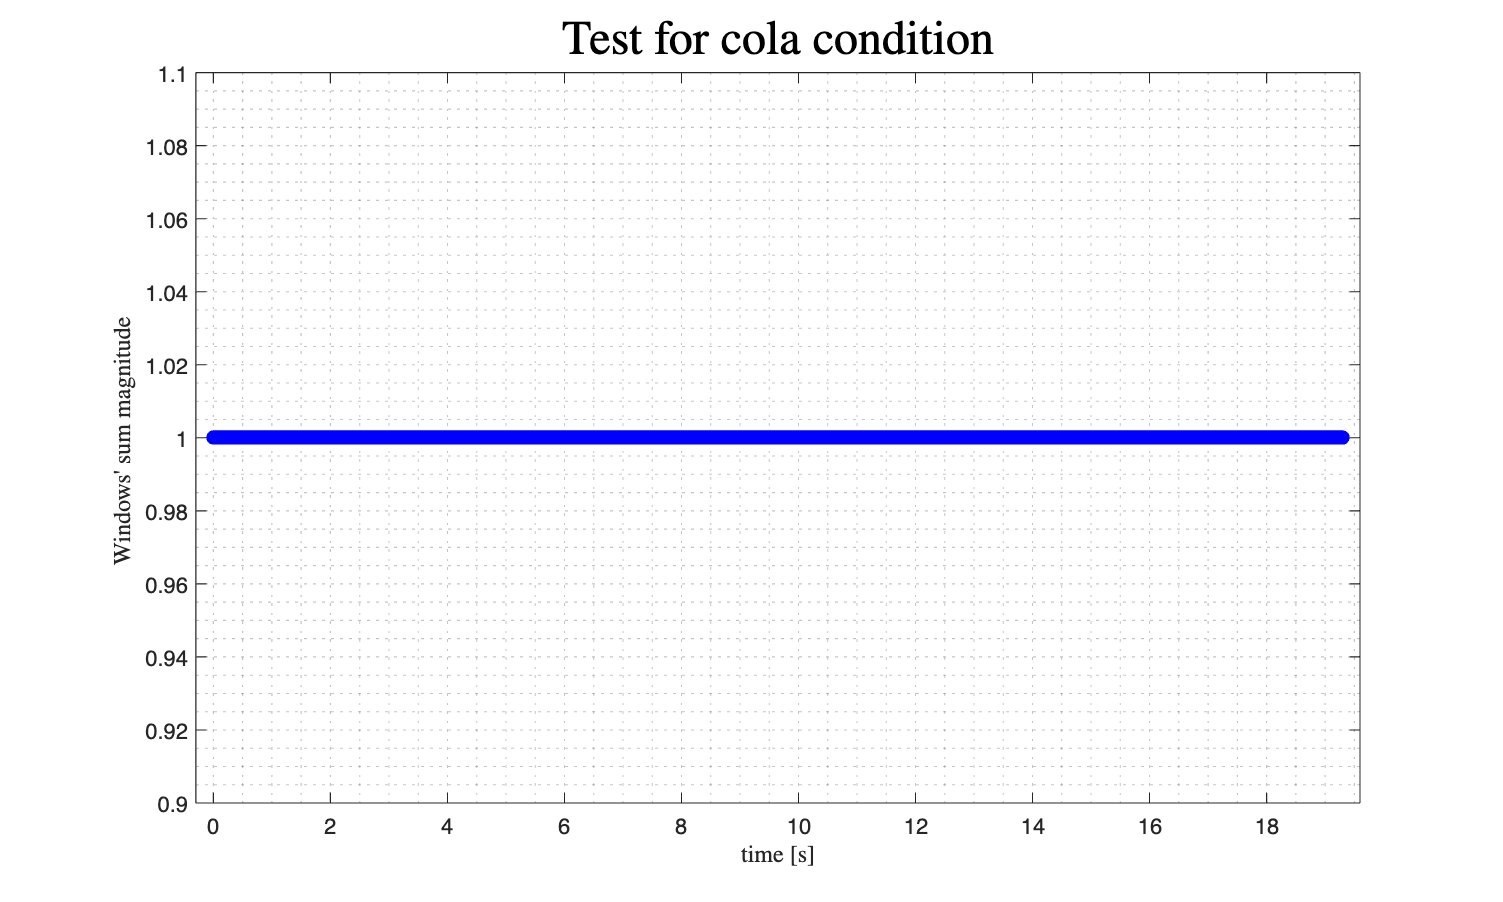

Precision check plots for piano signal


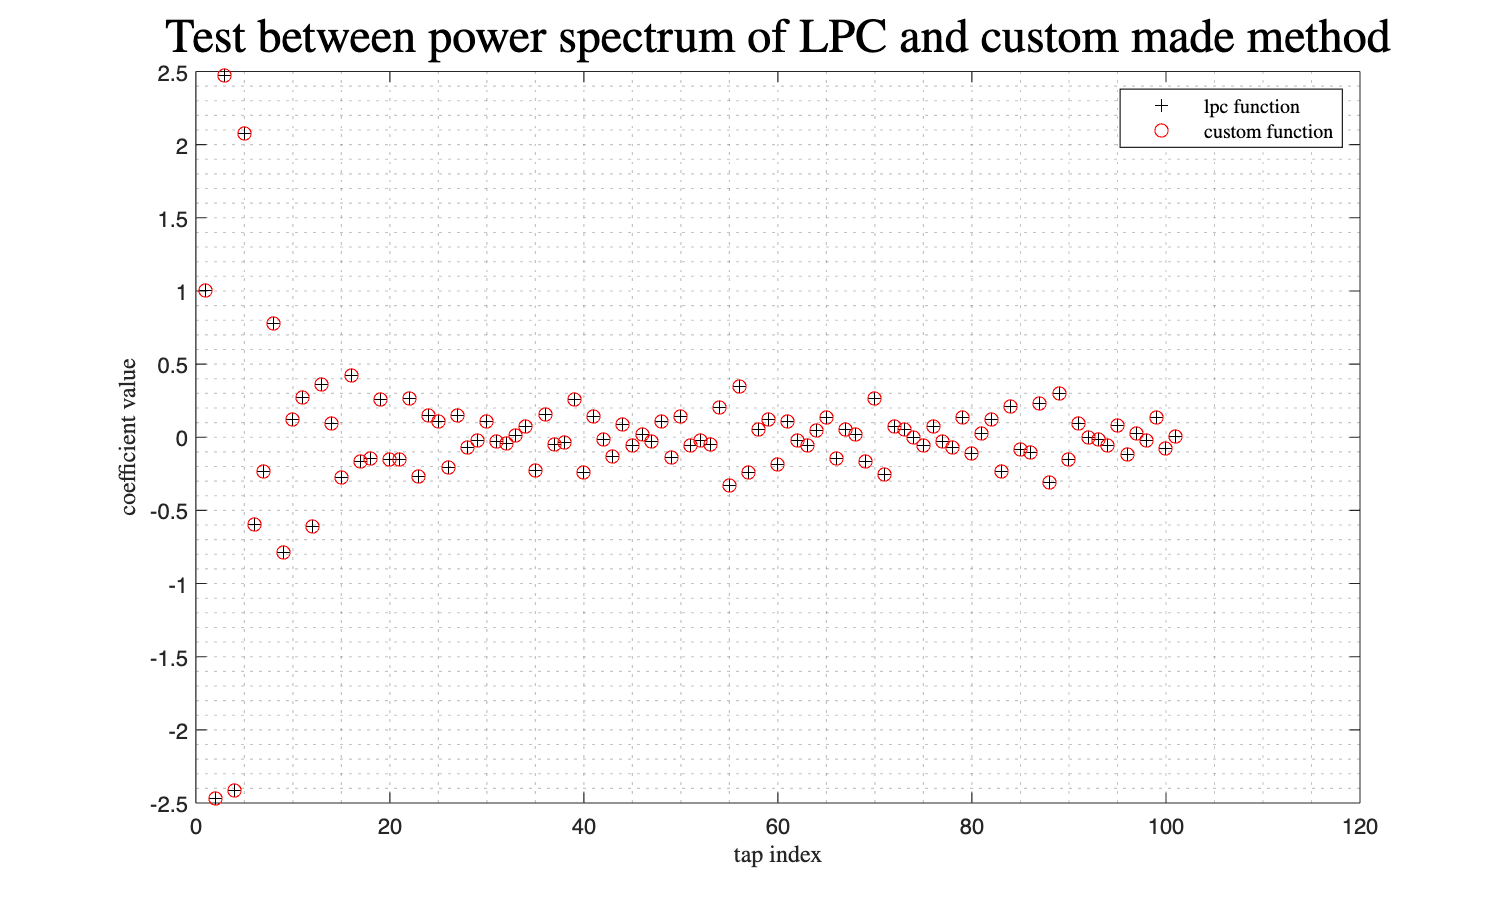

Precision check plots for speech signal


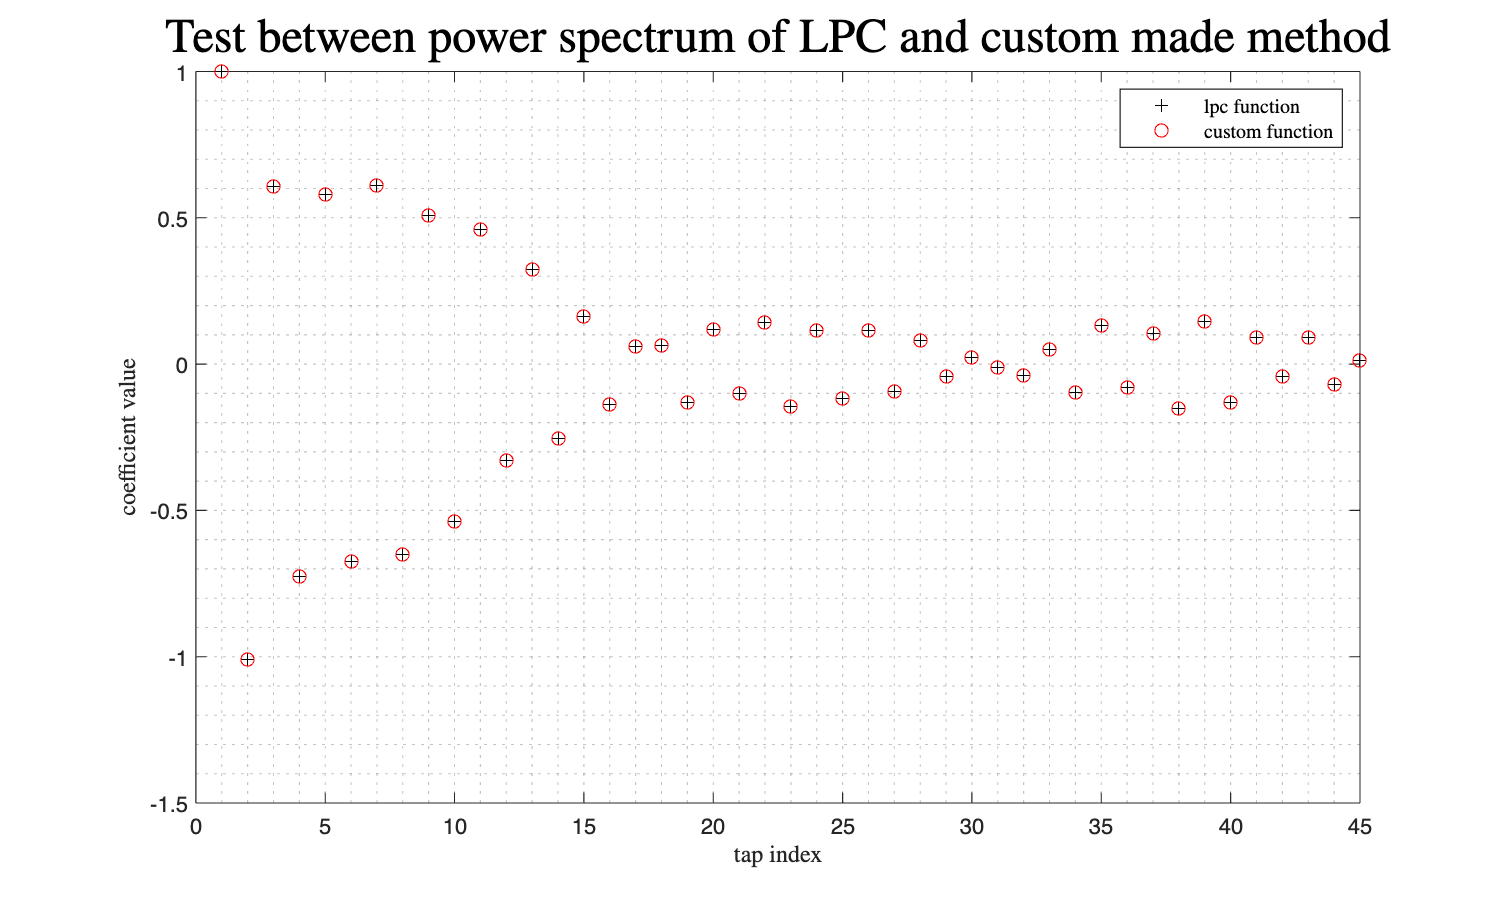

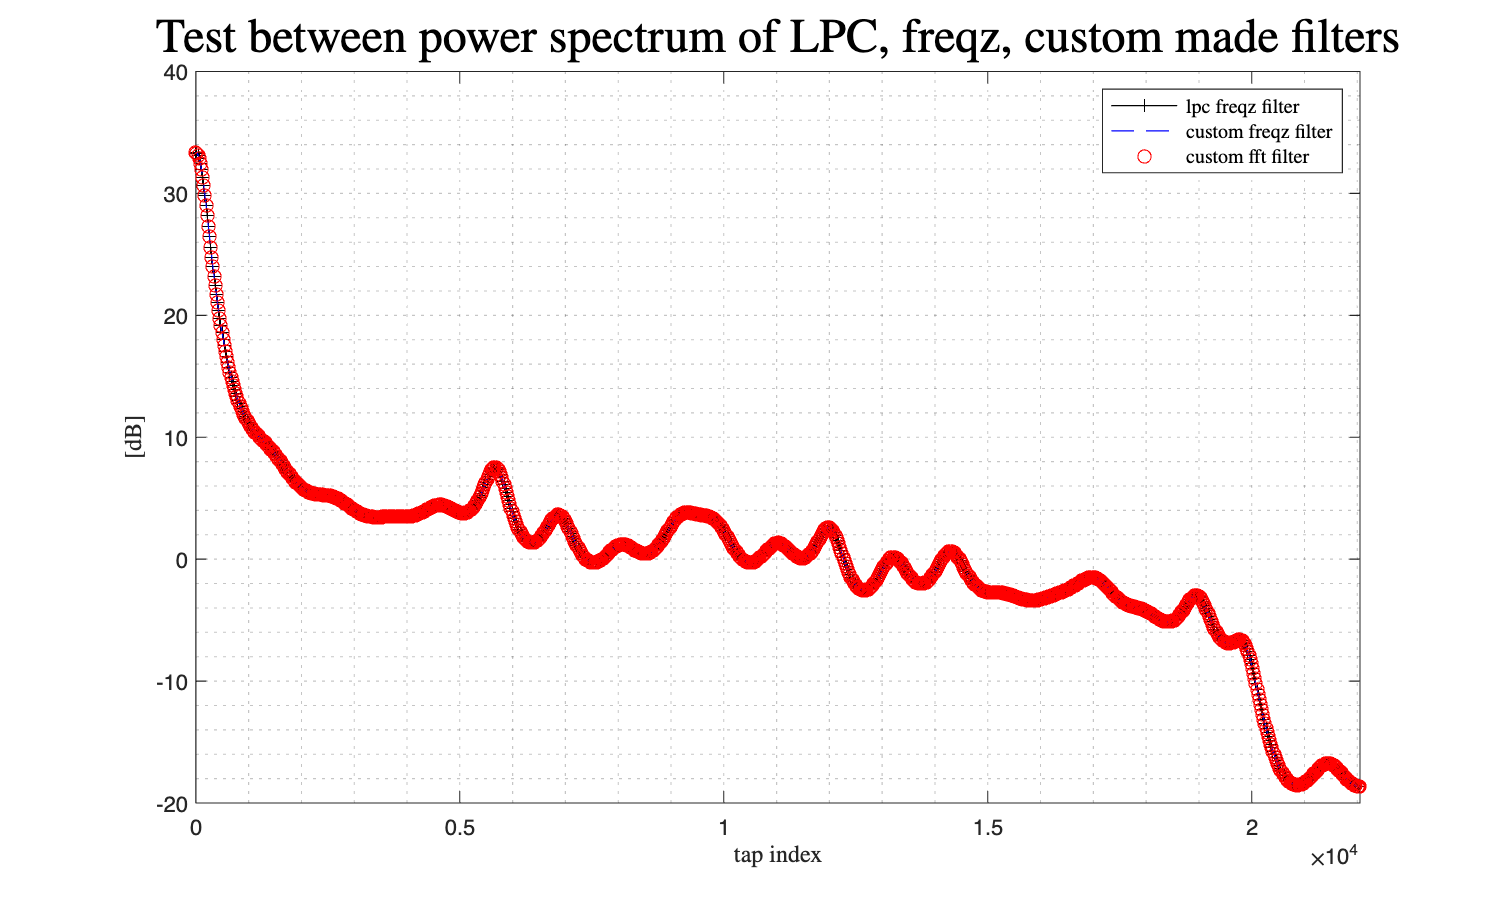

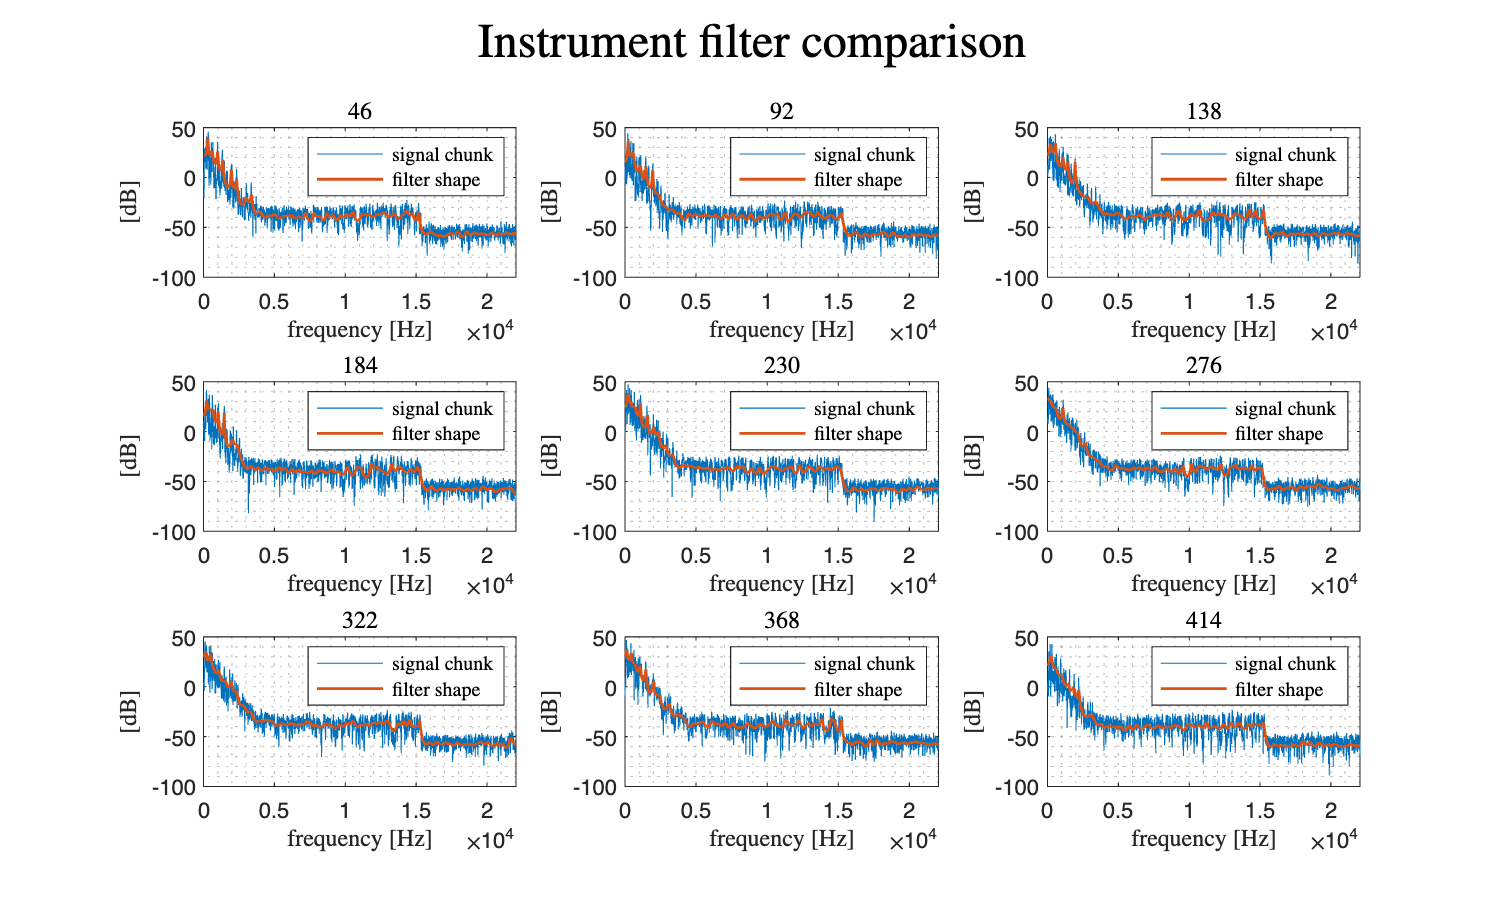

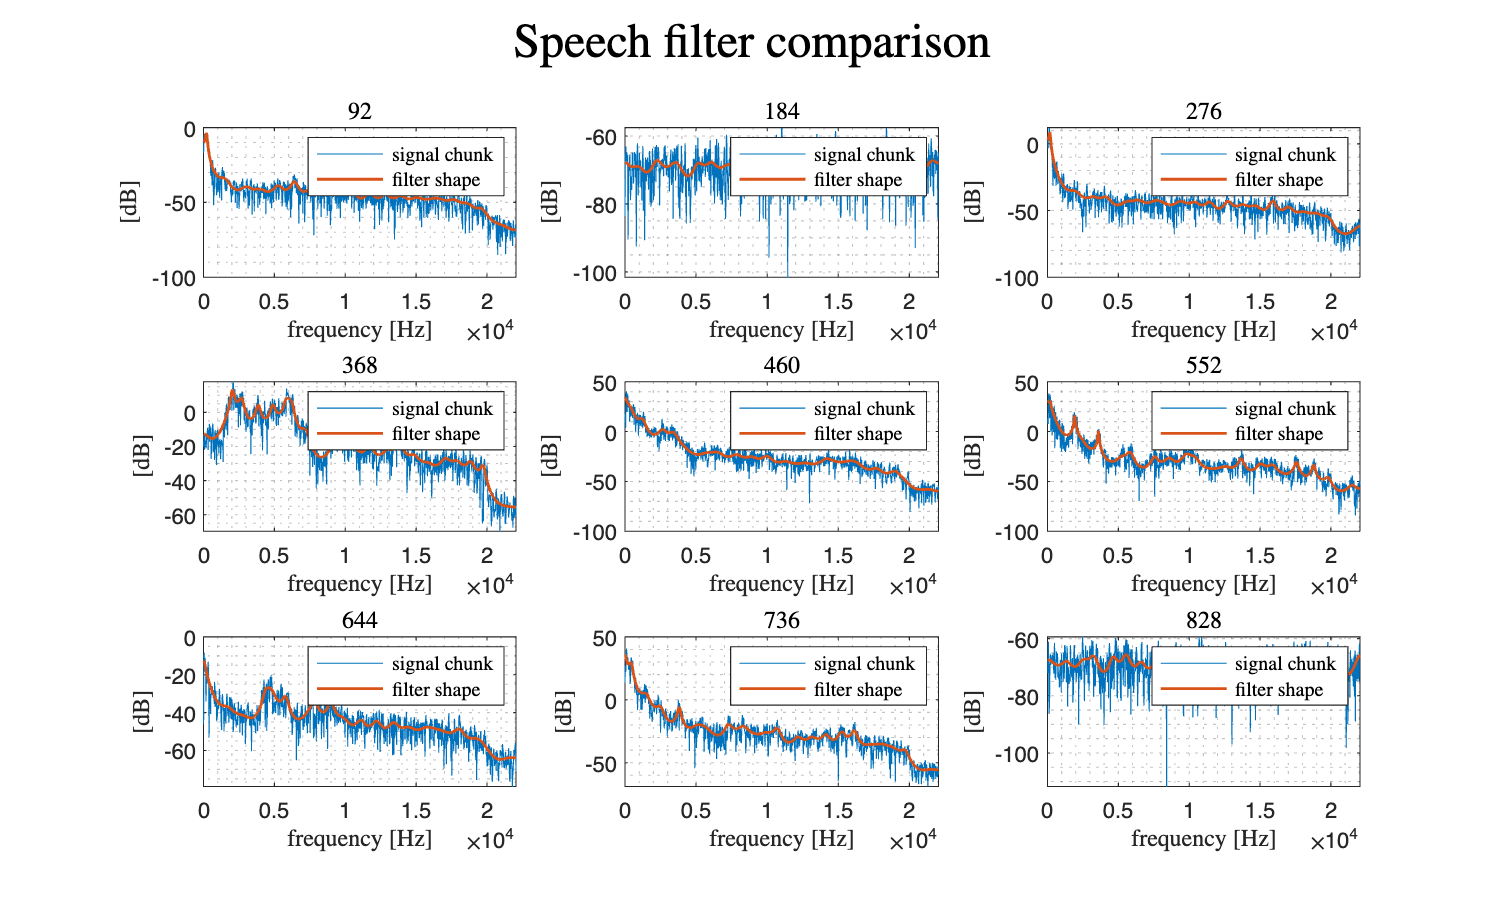

close all;

tic
talking_instr_res_name = "010_talking_instr_verb1.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,4096,44,100,"linSolve",0.3,10^-1,100000,"zeros",0,0,1,"","mean");

toc

Elapsed time is 4.756887 seconds.


## 02) Test for various threshold values using steepest descent

close all;clc;
disp("threshold 10^-1")

threshold 10^-1


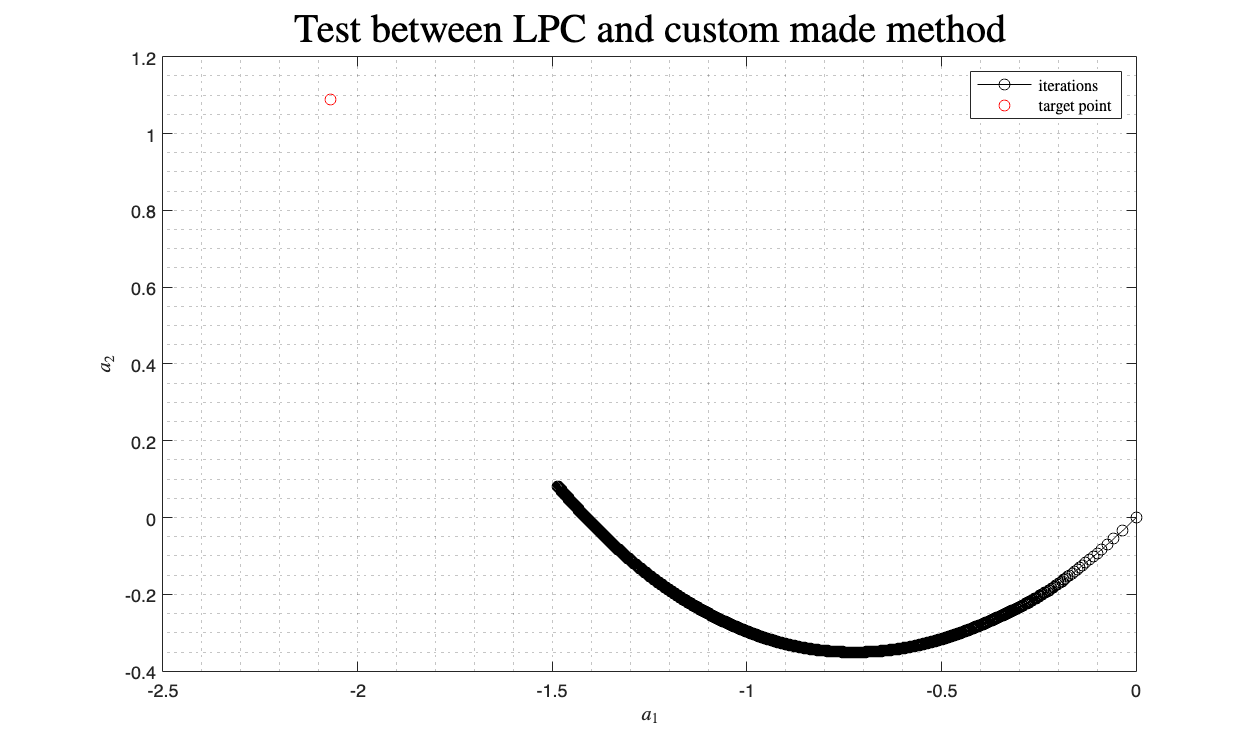

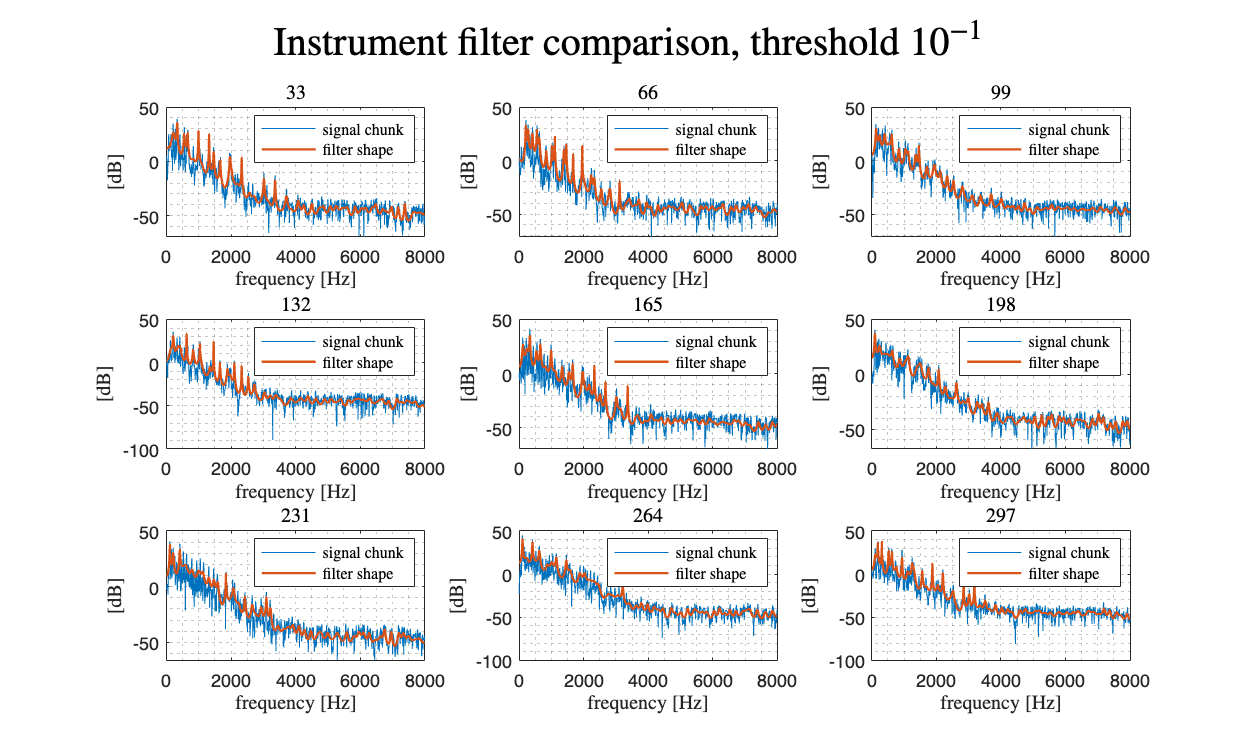

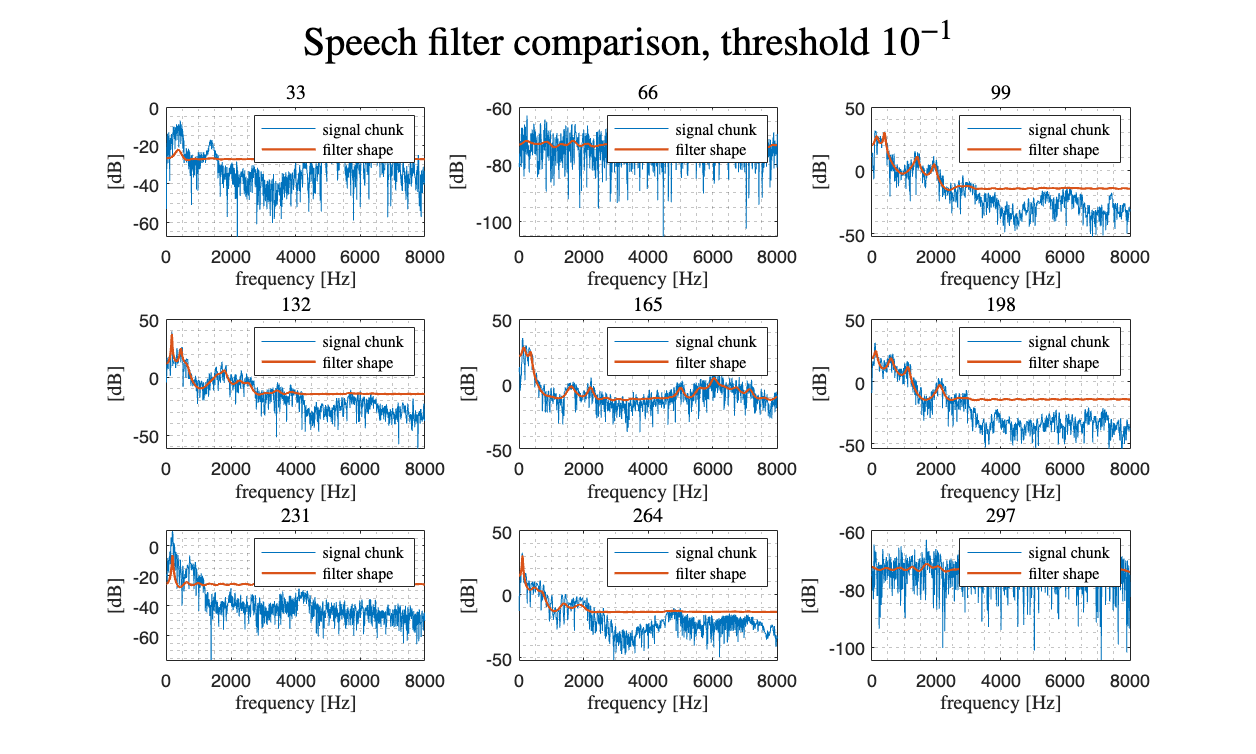

tic
talking_instr_res_name = "020_talking_instr_10_1.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-1,100000,"zeros",1,0,0,", threshold $10^{-1}$","mean");


toc

Elapsed time is 7.698015 seconds.


disp("threshold 10^-2")

threshold 10^-2


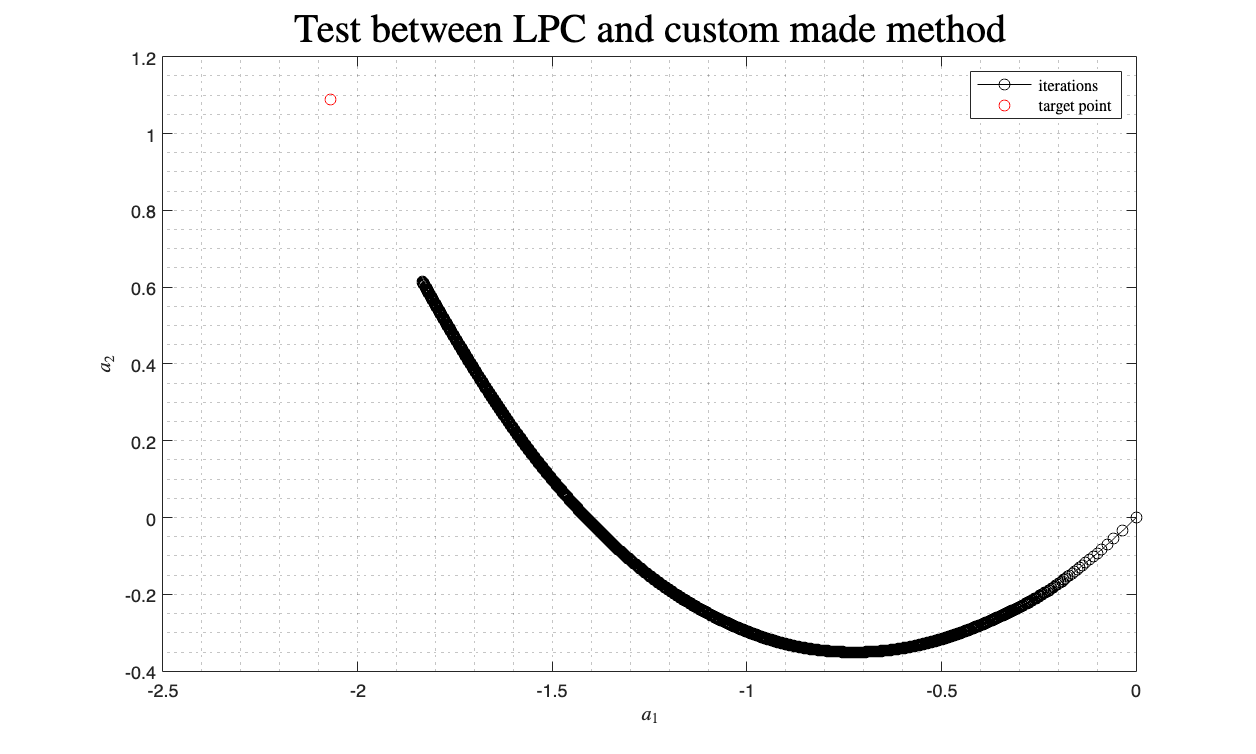

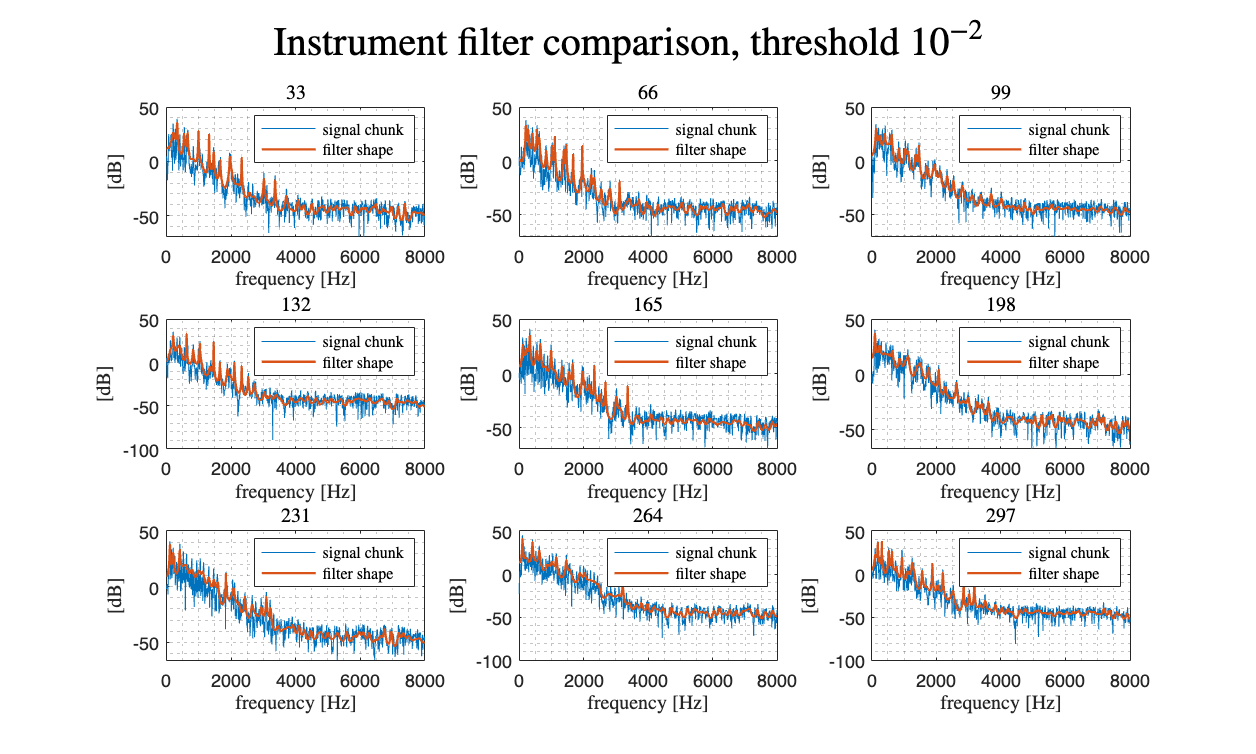

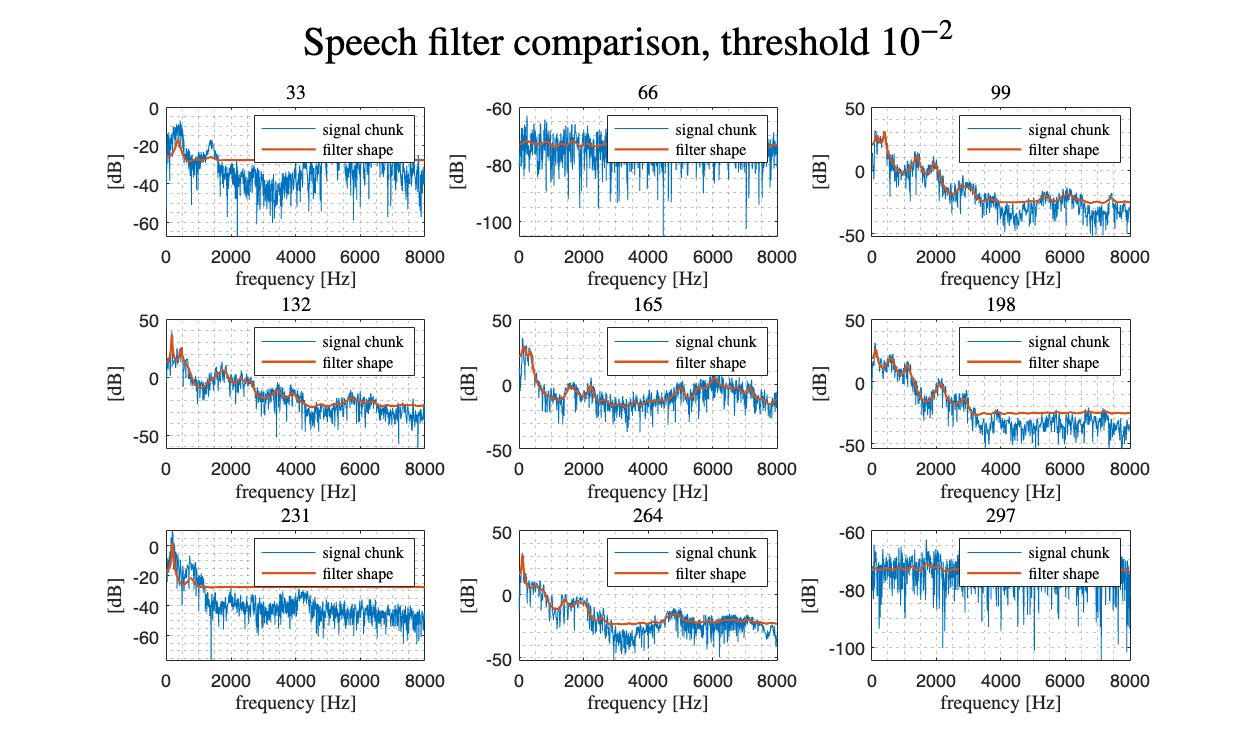

tic
talking_instr_res_name = "021_talking_instr_10_2.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-2,100000,"zeros",1,0,0,", threshold $10^{-2}$","mean");

toc

Elapsed time is 41.444409 seconds.


disp("threshold 10^-4")

threshold 10^-4


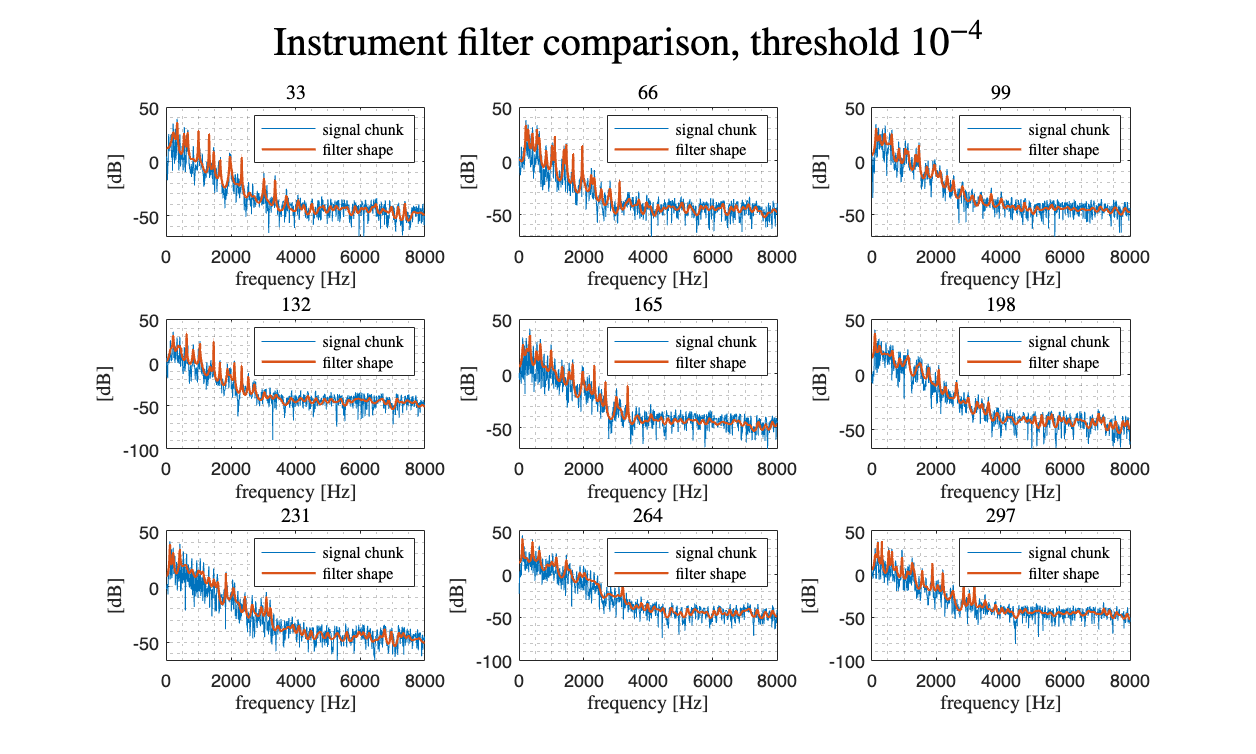

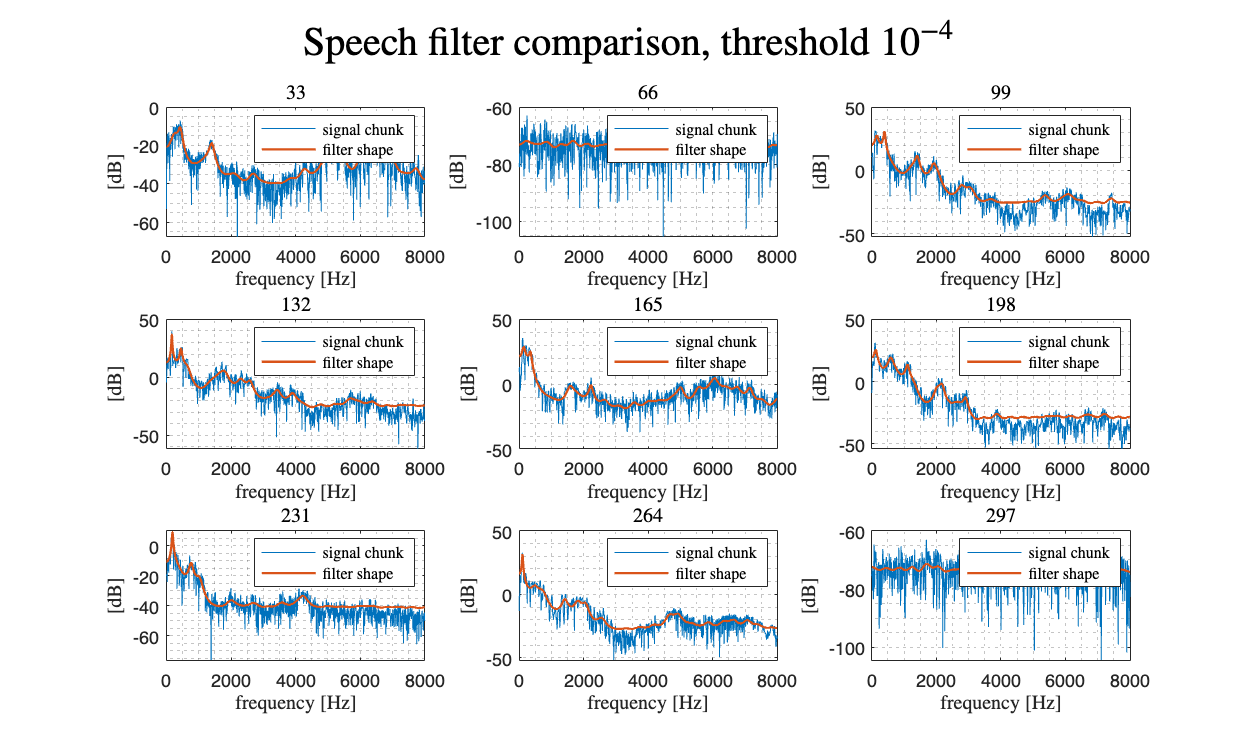


tic
talking_instr_res_name = "022_talking_instr_10_4.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"zeros",1,0,0,", threshold $10^{-4}$","mean");

toc

Elapsed time is 57.799814 seconds.


## 03) Test for various coefficients initialization values using steepest descent

disp("time for speech steepest descent equals to previous value")

time for speech steepest descent equals to previous value


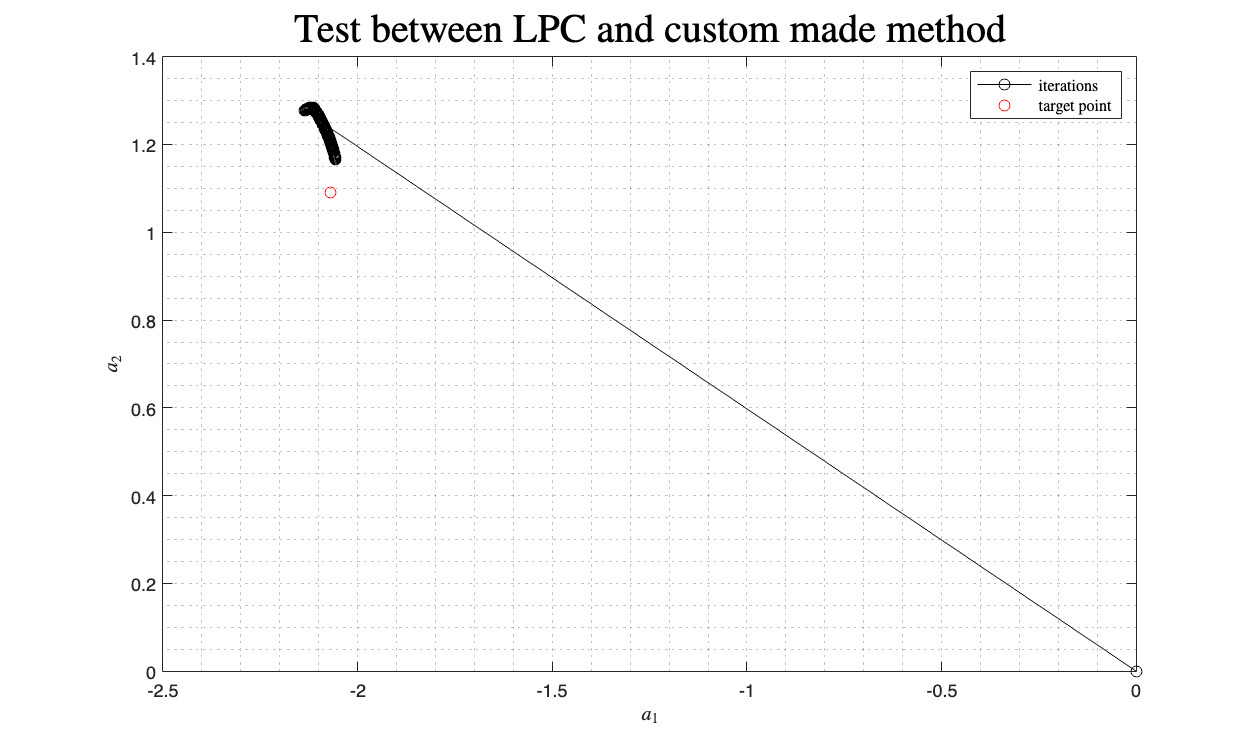

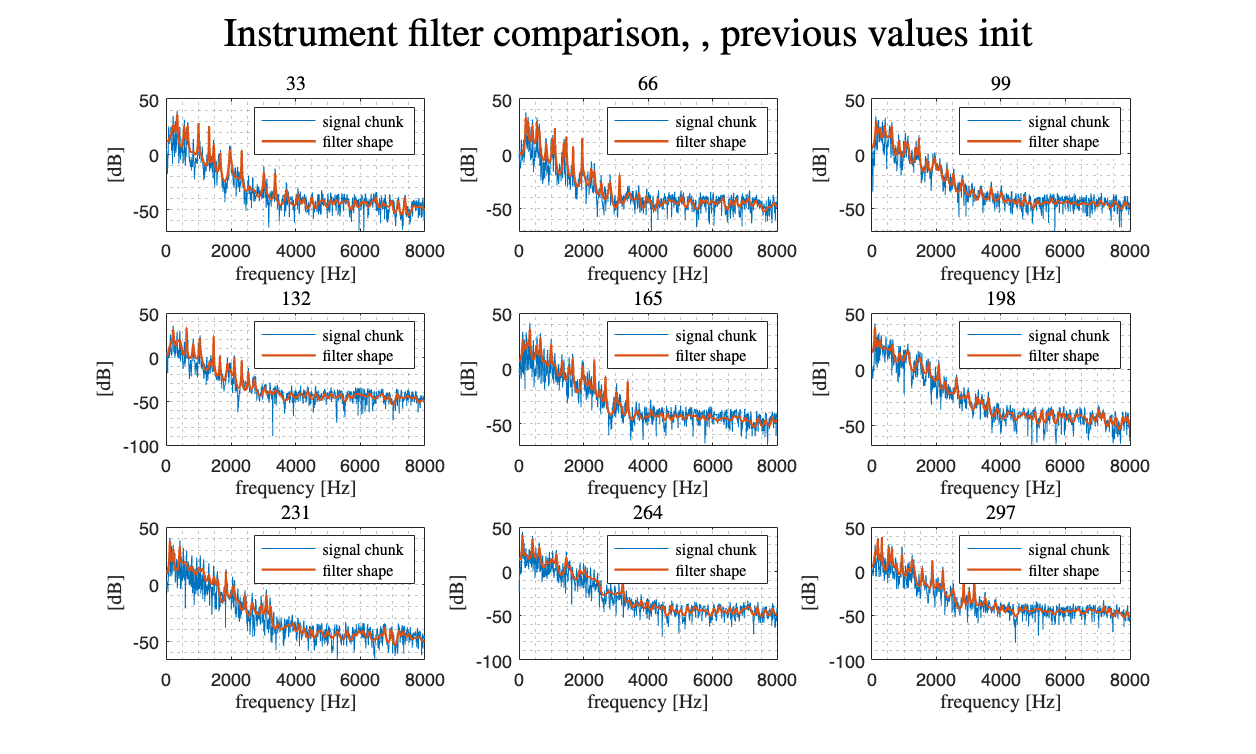

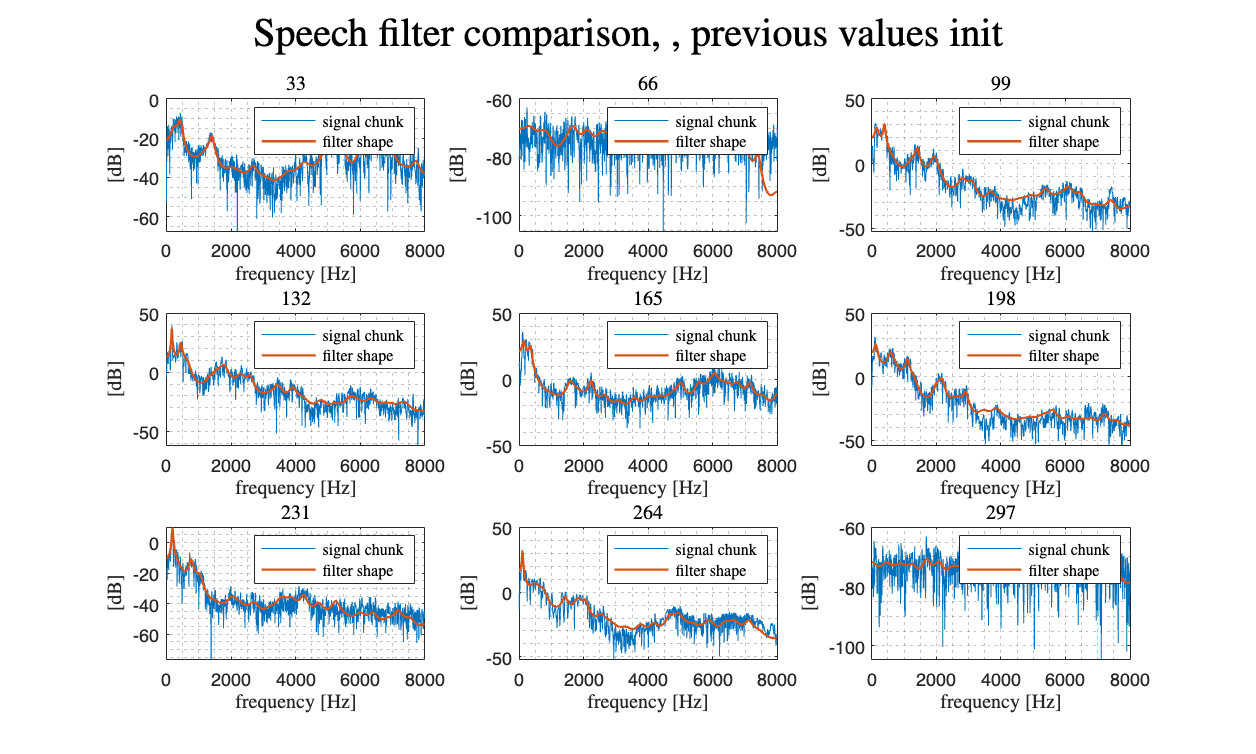


tic
talking_instr_res_name = "030_talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"prev",1,0,0,", previous values init","mean");

%main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"prev",1,0,0,"prev");
toc

Elapsed time is 56.695902 seconds.


disp("time for speech steepest descent equals to zero")

time for speech steepest descent equals to zero


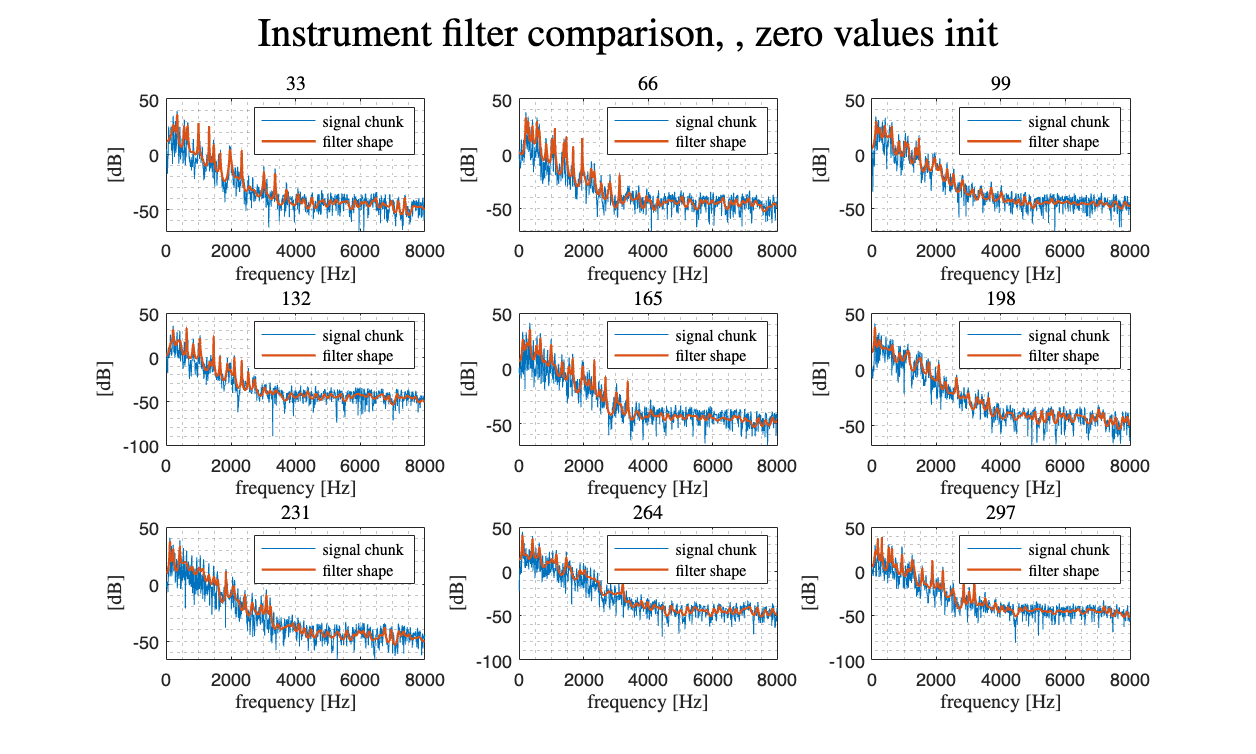

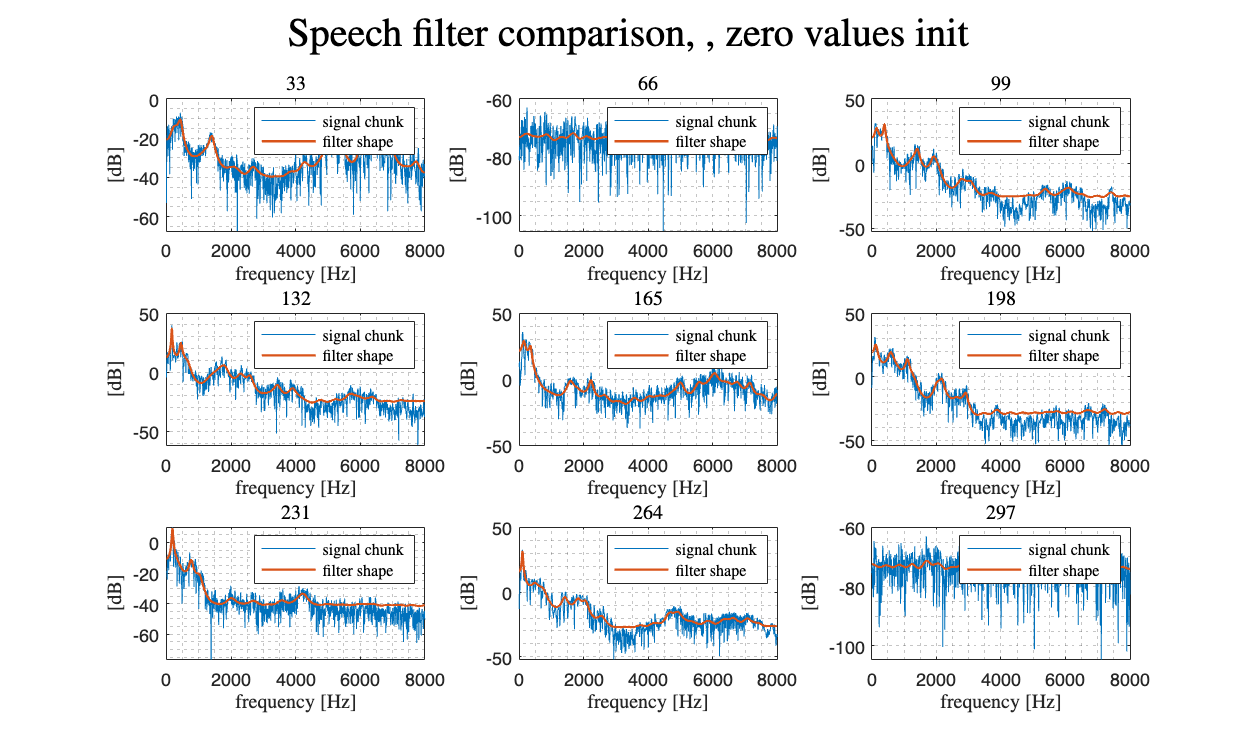



tic
talking_instr_res_name = "021_talking_instr_zeros.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"zeros",1,0,0,", zero values init","mean");


%main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"zeros",1,0,0,"zeros");
toc

Elapsed time is 56.277242 seconds.


disp("time for speech steepest descent equals to one")

time for speech steepest descent equals to one


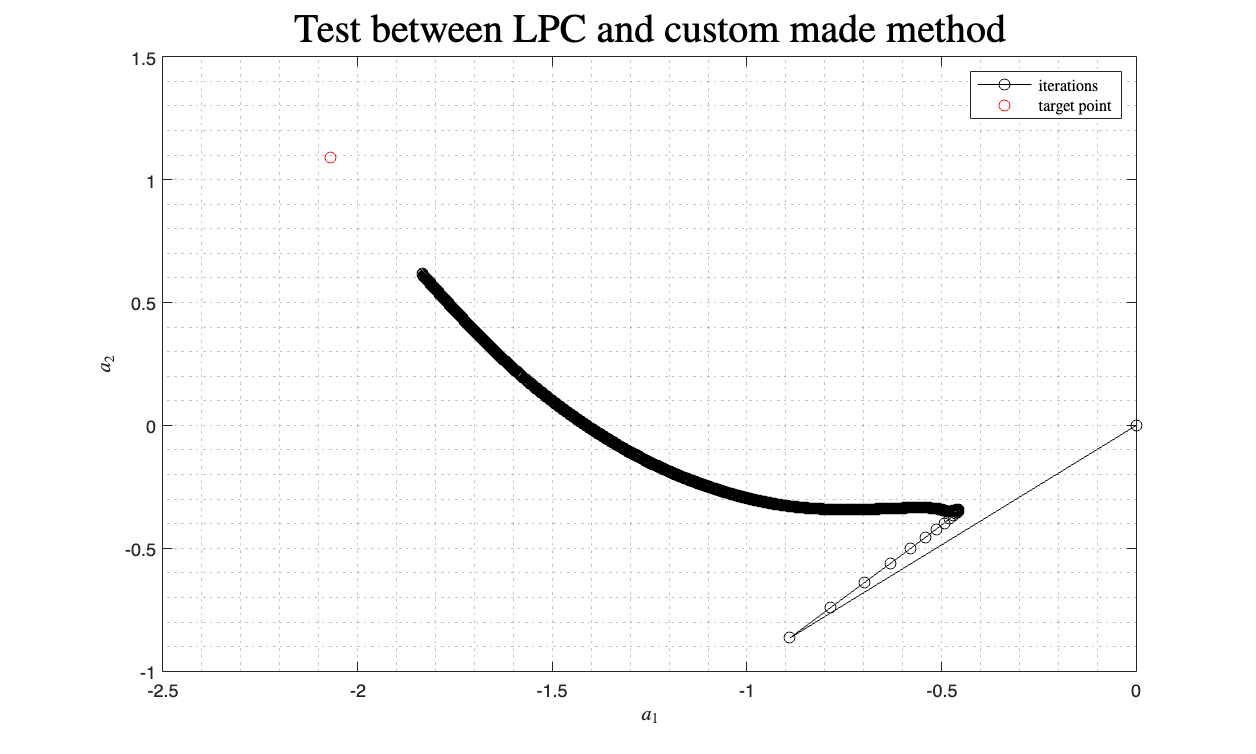

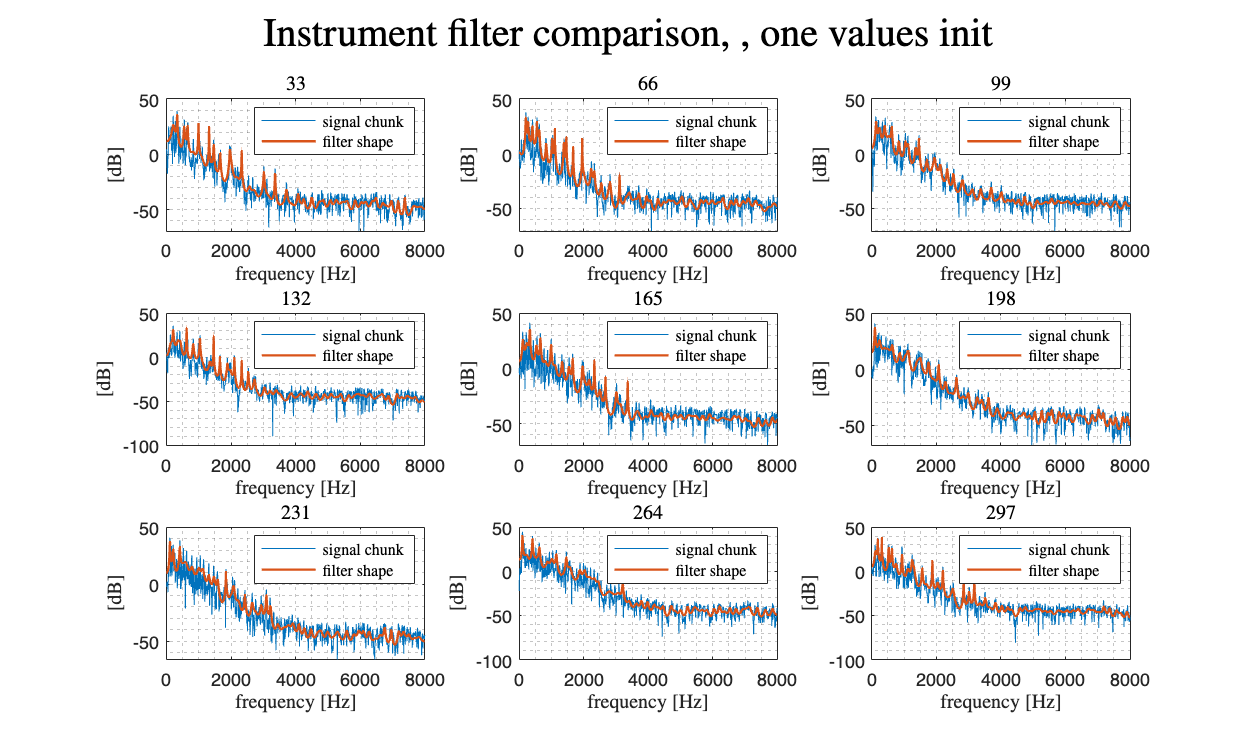

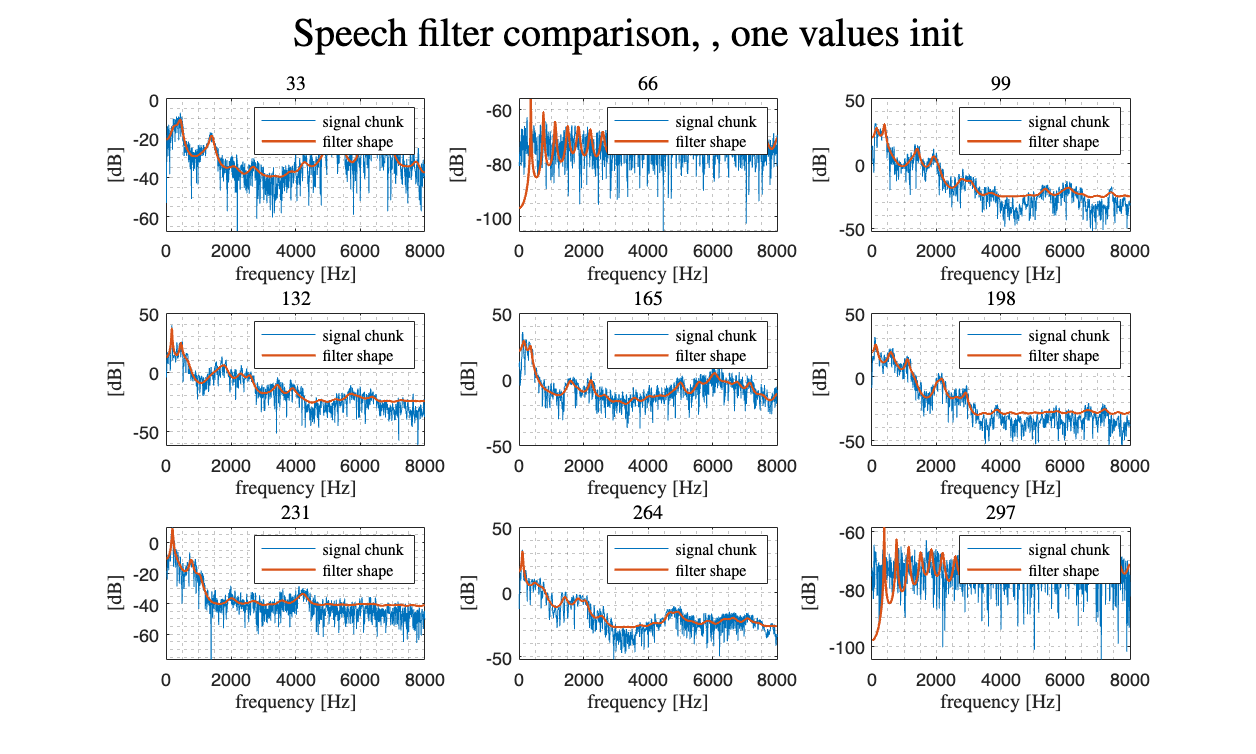


tic

talking_instr_res_name = "talking_instr_ones.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"ones",1,0,0,", one values init","mean");


%main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"ones",1,0,0,"ones");
toc

Elapsed time is 56.293849 seconds.



disp("time for speech steepest descent equals to random values")

time for speech steepest descent equals to random values


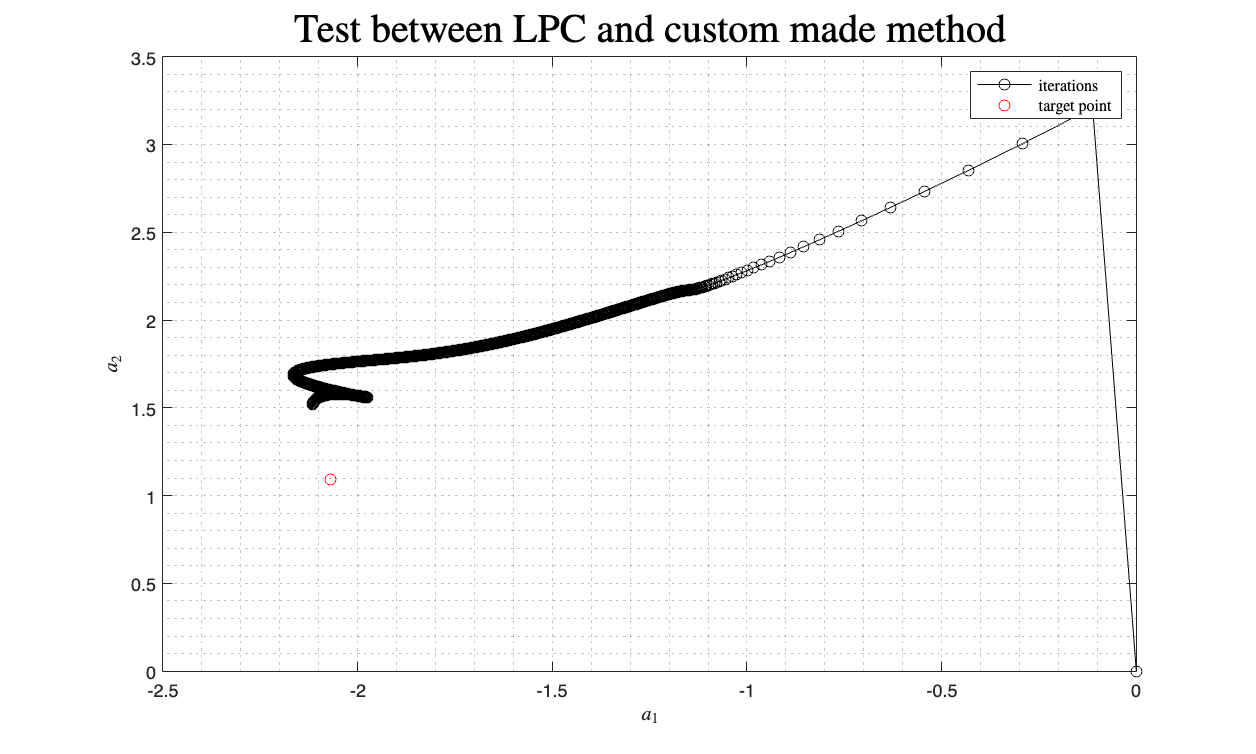

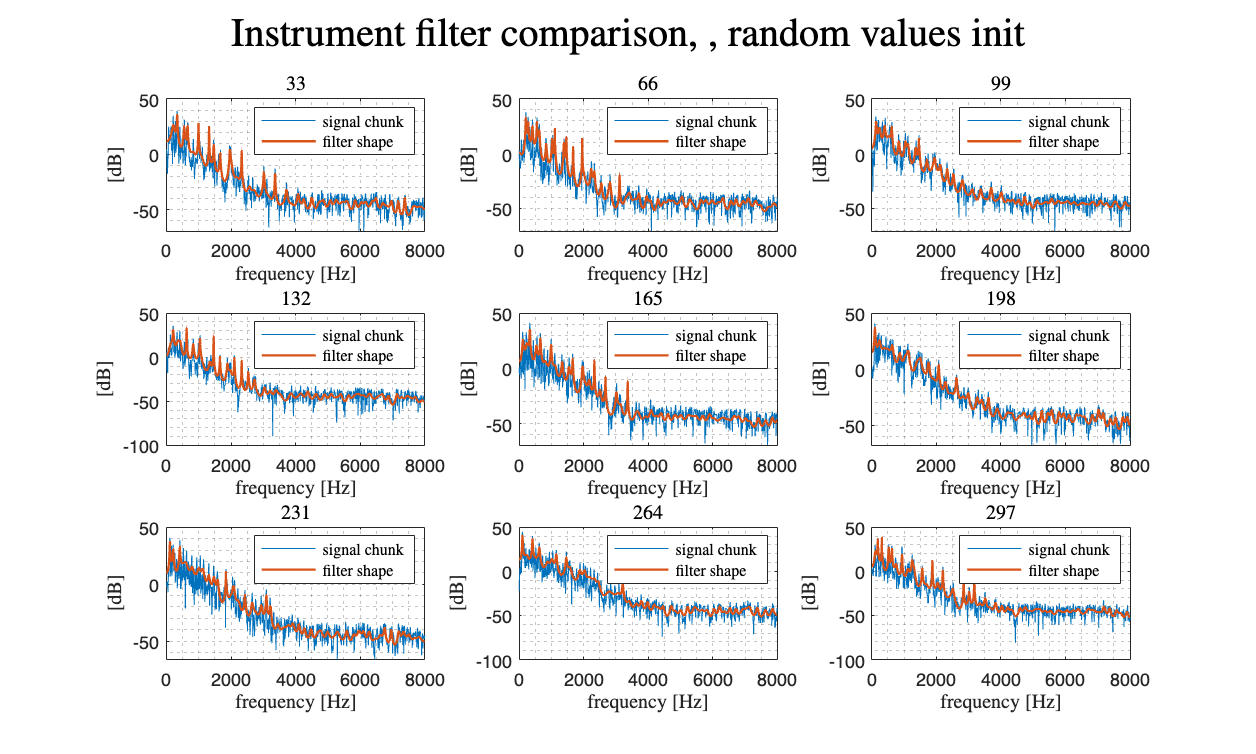

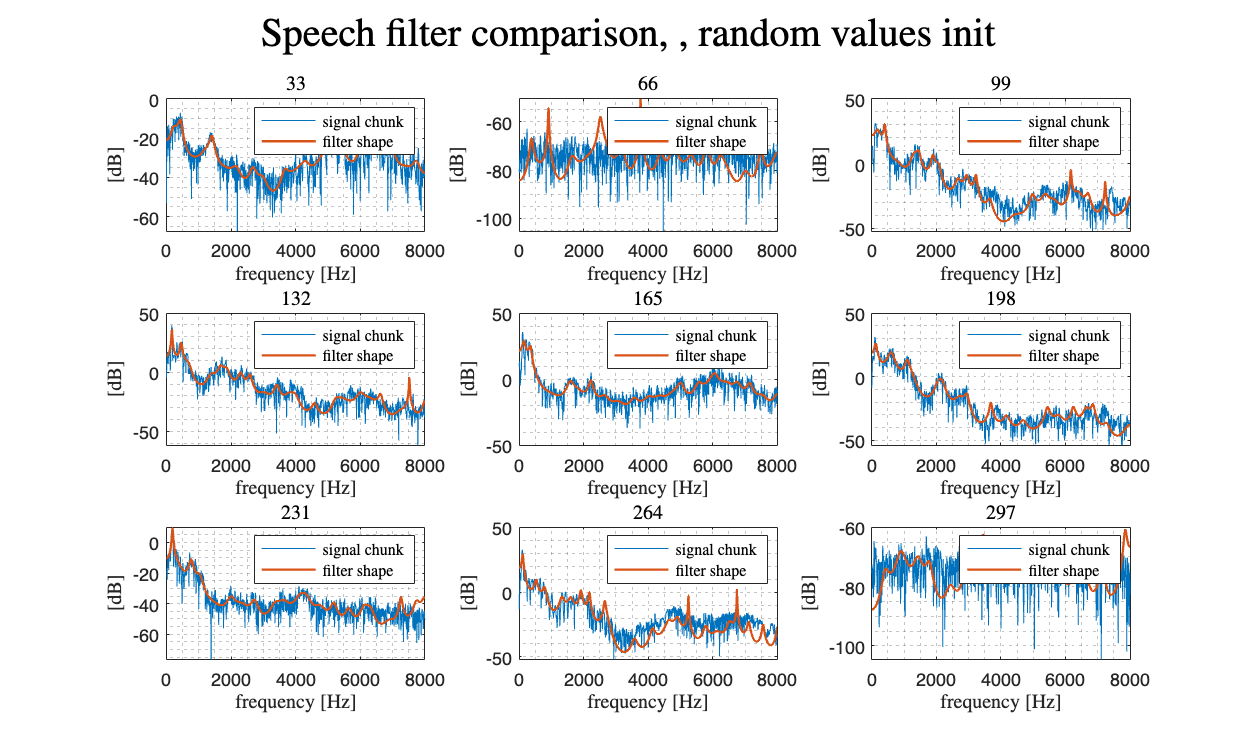



tic
talking_instr_res_name = "talking_instr_randn.wav";
main(instr_name, speech_name, talking_instr_res_name,2048,2048,44,100,"mixed1",0.3,10^-4,100000,"randn",1,0,0,", random values init","mean");


%main(instr_name, speech_name, talking_instr_res_name,"mixed1",0.3,0.5*10^-1,100000,"randn",1,0,0,"prev");
toc

Elapsed time is 58.252680 seconds.



%sound(avviso(1:5*44100),44100);